% clearvars -except current_faulty current_healthy time_healthy time_faulty current_exp_healthy time_exp_halthy current_exp_faulty time_exp_faulty PSD_dB_exp_h PSD_dB_exp_f PSD_dB PSD_dB_f f f2 f_exp_h f_exp_f;
clc;
clear all;
% [filename, pathname] = uigetfile({'*.csv', 'CSV Files (*.csv)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select a CSV file');
% fullpath = fullfile(pathname, filename);
% data_noload = readtable(fullpath, 'Range', 'A:B'); 
[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_noload = readtable(fullpath, 'Range', 'A:B'); 
dataMatrix = table2array(data_noload);
current_exp_healthy = dataMatrix(:,2);
time_exp_healthy = dataMatrix(:,1);
% [filename, pathname] = uigetfile({'*.csv', 'CSV Files (*.csv)'; ...
%                                   '*.*', 'All Files (*.*)'}, ...
%                                   'Select a CSV file');
% fullpath = fullfile(pathname, filename);
% data_noload_2 = readtable(fullpath, 'Range', 'A:B'); 
[filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                  '*.*', 'All Files (*.*)'}, ...
                                  'Select an Excel file');
fullpath = fullfile(pathname, filename);
data_noload_2 = readtable(fullpath, 'Range', 'A:B'); 
dataMatrixx = table2array(data_noload_2);
current_exp_faulty = dataMatrixx(:,2);
time_exp_faulty = dataMatrixx(:,1);


##  30 Cycles for Steady State:

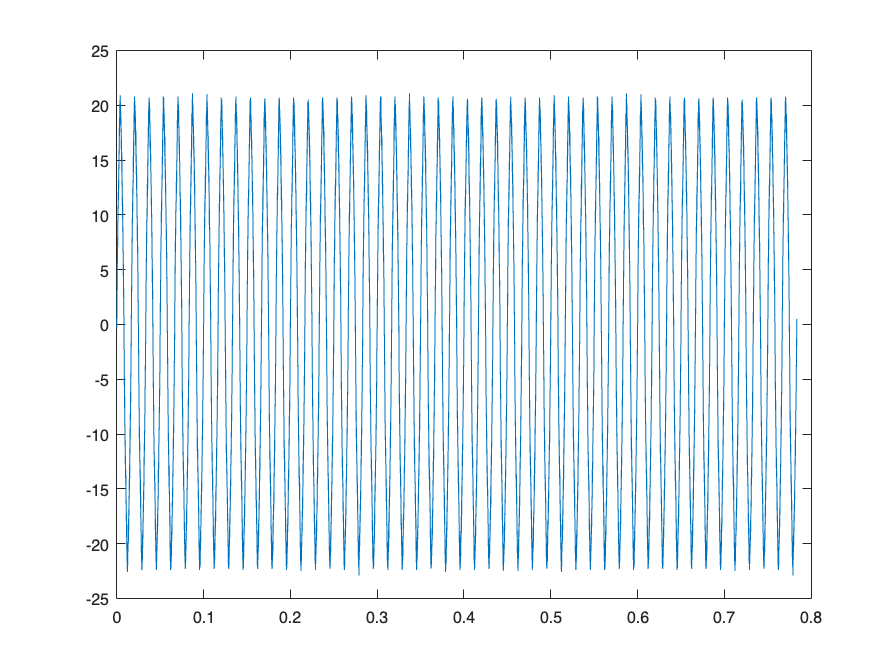

threshold_time = 0;
num_zero_crossings_f = 1000;
num_zero_crossings_h = 4500;
[time_lcf, current_lcf] = plot_cycles(time_exp_faulty, current_exp_faulty, threshold_time, num_zero_crossings_f);
[time_lch, current_lch] = plot_cycles(time_exp_healthy, current_exp_healthy, threshold_time, num_zero_crossings_h);
figure;
plot(time_lcf,current_lcf);

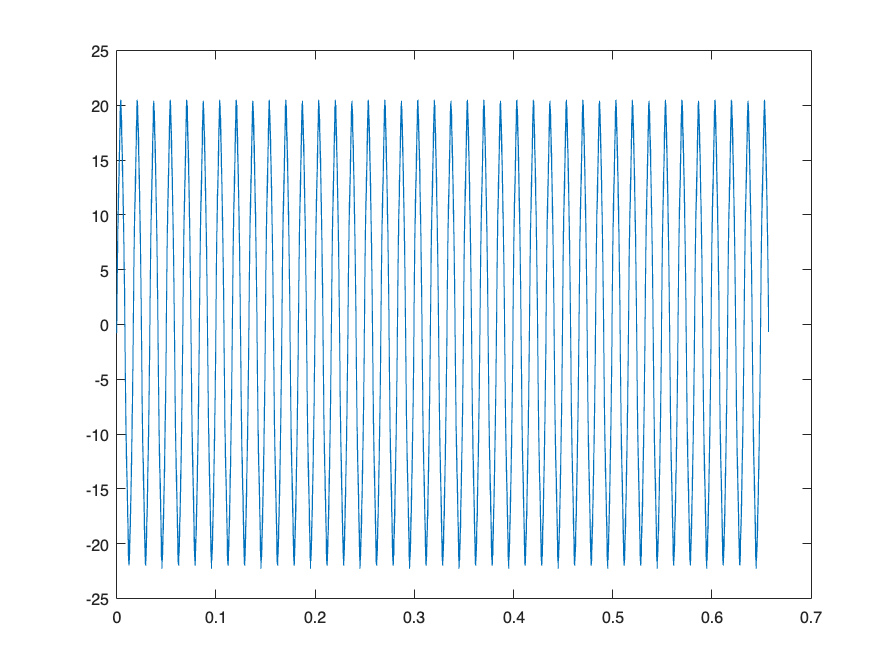

plot(time_lch,current_lch);

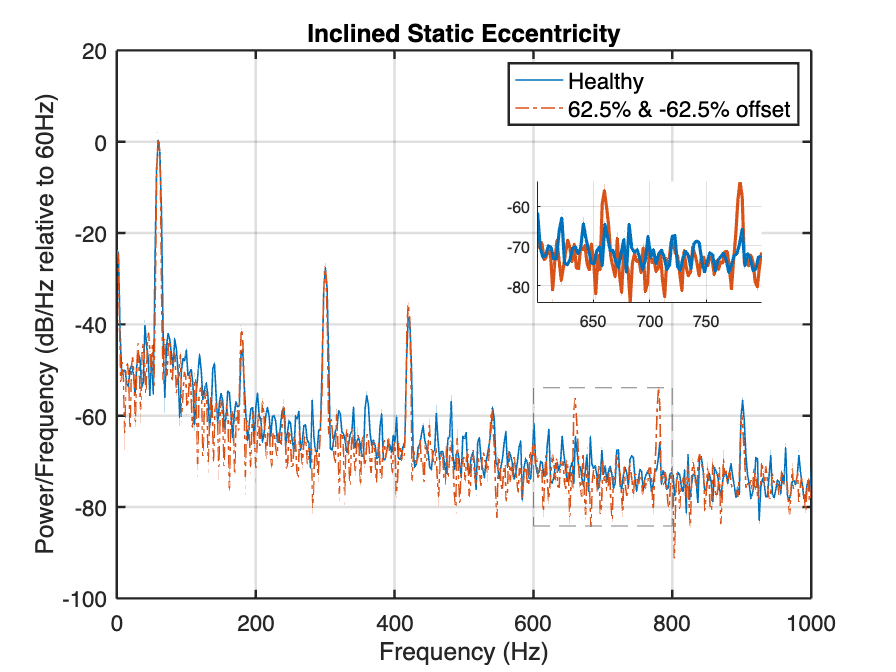

segment_fraction = 0.5;

% First dataset calculations
[f_exp_h, PSD_dB_exp_h, P_at_60Hz] = calculate_psd(time_lch, current_lch, segment_fraction);

% Second dataset calculations
[f_exp_f, PSD_dB_exp_f, P_at_60Hz_2] = calculate_psd(time_lcf, current_lcf, segment_fraction);


plotPSD(PSD_dB_exp_h, f_exp_h, PSD_dB_exp_f, f_exp_f, true, [600, 800]);